rootDir = 'C:\Users\kpiec\OneDrive - Politechnika Łódzka\Studia\2Sem3\magisterka\pomiary\IWR1843BOOST';
dba = buildTrackingDatabase(rootDir);

T1=struct2table(dba);
idx = T1.gait ~="snk" & T1.gait ~="test" & startsWith(T1.place,"hall") & cellfun(@str2num, T1.person)<6;

T = varfun(@string, T1(idx,:));
T.Properties.VariableNames=T1.Properties.VariableNames;

T.numFrames = arrayfun(@str2num, T.numFrames);

activities = {
    "sw" ,"Marsz"
    "fw" ,"Szybki marsz"
    "run","Bieg"
    };

places={
    "hall-along","A"
    "hall-end","B"
    }

places = 2×2 cell array
    {["hall-along"]}    {["A"]}
    {["hall-end"  ]}    {["B"]}




for i = 1:height(T)
    x=find(strcmp(T.gait(i),string(activities(:,1))));
    if x
    T.gait(i) = string(activities(x,2));
    end
    x=find(strcmp(T.place(i),string(places(:,1))));
    if x
        T.place(i) = string(places(x,2));
    end
    
end

T.Measurement = ones(height(T),1);

statsTable = groupsummary(T,{'place','gait','person'},"sum",'numFrames');

statsTable = statsTable(:, ...
    {'place','gait','person','GroupCount','sum_numFrames'});

statsTable.Properties.VariableNames = { ...
    'Scenariusz',...
    'Typ ruchu',...
    'Osoba',...
    'Liczba pomiarów',...
    'Liczba ramek'};

statsTable = sortrows(statsTable,...
    {'Scenariusz','Typ ruchu','Osoba'});
disp(statsTable)

    Scenariusz      Typ ruchu       Osoba    Liczba pomiarów    Liczba ramek
    __________    ______________    _____    _______________    ____________
       "A"        "Bieg"             "0"            2                709    
       "A"        "Bieg"             "3"            2               1453    
       "A"        "Bieg"             "5"            2               1410    
       "A"        "Marsz"            "0"           10               1438    
       "A"        "Marsz"            "1"           10               1055    
       "A"        "Marsz"            "2"           10               2339    
       "A"        "Marsz"            "3"            2               1452    
       "A"        "Marsz"            "5"            3               2202    
       "A"        "Szybki marsz"     "0"            8       

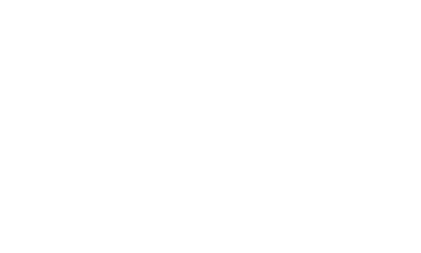

gaits = {['sw',"Marsz"],['fw',"Szybki marsz"],['run',"Bieg"]};
places = {['hall-end',"scenariusz B"],['hall-along',"scenariusz A"]};
mapTypes = {'RA','RD'};

figure('Color','w');

tiledlayout(numel(mapTypes),numel(places), ...
    'TileSpacing','compact','Padding','compact');


for m = 1:numel(mapTypes)

    mapType = mapTypes{m};

    for p = 1:numel(places)

        placeField = matlab.lang.makeValidName(places{p}(1));

        CM = zeros(numel(gaits));

        for gt = 1:numel(gaits)

            s = stats.(mapType).(placeField).(gaits{gt}(1)).samples;

            if sum(s) > 0
                CM(gt,:) = s ./ sum(s);
            end

        end

        nexttile

        imagesc(100*CM);
        axis image

        colormap(parula)
        colorbar

        clim([0 100]);

        xticks(1:numel(gaits));
        yticks(1:numel(gaits));

        xticklabels(cellfun(@(g) g(2),gaits));
        yticklabels(cellfun(@(g) g(2),gaits));

        xlabel('Wyznaczone');
        ylabel('Oczekiwane');

        title(sprintf('%s | %s',mapType,places{p}(2)));

        for r = 1:size(CM,1)
            for c = 1:size(CM,2)

                text(c,r,...
                    sprintf('%.1f%%',100*CM(r,c)),...
                    'HorizontalAlignment','center',...
                    'Color','w',...
                    'FontWeight','bold');

            end
        end

    end
end

Unable to perform assignment because the indices on the left side are not compatible with the size of the right side.

figure('Color','w');

t = tiledlayout(1,2,'TileSpacing','compact','Padding','compact');

for m = 1:numel(mapTypes)

    nexttile

    missRate = zeros(numel(places),numel(gaits));

    for p = 1:numel(places)

        placeField = matlab.lang.makeValidName(places{p}(1));

        for g = 1:numel(gaits)

            st = stats.(mapTypes{m}).(placeField).(gaits{g}(1));

            totalTracks = ...
                st.acceptedTracks + ...
                st.rejectedTracks;

            if totalTracks > 0
                missRate(p,g) = ...
                    st.rejectedTracks / totalTracks;
            end

        end
    end

    bh = bar(100*missRate);

    ylabel('Odrzucone ścieżki [%]');

    xticklabels(cellfun(@(g) g(2),places));

    title(mapTypes{m});

    grid on
end

leg = legend(cellfun(@(g) g(2),gaits));
leg.Layout.Tile = 'north';
leg.Orientation = 'horizontal';

for m = 1:numel(mapTypes)

    missRate = zeros(numel(gaits),numel(places));

    for p = 1:numel(places)

        placeField = matlab.lang.makeValidName(places{p});

        for g = 1:numel(gaits)

            st = stats.(mapTypes{m}).(placeField).(gaits{g});

            total = st.acceptedTracks + st.rejectedTracks;

            if total > 0
                missRate(g,p) = st.rejectedTracks/total;
            end

        end
    end

    figure('Color','w');

    imagesc(100*missRate);

    colormap(jet);
    clim([0 100])
    colorbar;

    xticks(1:numel(places));
    yticks(1:numel(gaits));

    xticklabels(places);
    yticklabels(gaits);

    xlabel('Place');
    ylabel('Expected gait');

    title(sprintf('%s miss rate [%%]',mapTypes{m}));

    for r = 1:size(missRate,1)
        for c = 1:size(missRate,2)

            text(c,r,...
                sprintf('%.1f%%',100*missRate(r,c)),...
                'HorizontalAlignment','center',...
                'Color','w',...
                'FontWeight','bold');

        end
    end
end

trackLogArr = [trackLog{:}];
trackLogArr = [trackLogArr(:).State; trackLogArr(:).UpdateTime; double([trackLogArr(:).TrackID])];

gndTruth = [3 3 6 6 3; 0 23 23 6 6]*0.305;
radarAngle = -17;
colors = lines;
minTrackLen=10;

figure(20)
clf
if isEndRecording
    subplot(1,2,1)
    plot(gndTruth(1,:),gndTruth(2,:),":","Color","#aaaaaa","LineWidth",2);
    rotMat = rotz(radarAngle);
    rotMat = rotMat(1:2,1:2);
else
    rotMat = eye(2,2);
end
minTrackLen=10;
ids = unique(trackLogArr(end,:));
ids = ids(arrayfun(@(id) sum(trackLogArr(end,:)==id),ids)>minTrackLen);
for n=1:numel(ids)
    id=ids(n);
    col = colors(mod(n,size(colors,1)),:);
    subplot(1,2,1)
    part = trackLogArr(:,trackLogArr(end,:)==id);
    XY=rotMat*part([1 3],:); % rotate according to radar position
    hold on
    plot(XY(1,:),XY(2,:),'Color',col); % trail
    hold off
    subplot(1,2,2)
    hold on
    plot(part(end-1,:),hypot(part(2,:),part(4,:)),'Color',col); % speed
    hold off
end
subplot(1,2,1)
xlabel("Dystans [m]")
ylabel("Dystans [m]")
hold on
plot(0,0,"v",'Color','r','LineWidth',1)
axis equal fill;
hold off
subplot(1,2,2)
% legend(string(ids))
xlabel("Czas [s]")
ylabel("Prędkość [m/s]")


figure(21)
clf
tLog = [targetsLog{:}];
tLog(1:2, :) = rotMat * tLog(1:2, :);
hold on
scatter(tLog(1,:), tLog(2,:), 40, tLog(3,:), '*')
if isEndRecording
    plot(gndTruth(1,:),gndTruth(2,:),":","Color","#aaaaaa","LineWidth",2);
end
hold off
title("Punkty analizowane w procesie RA")

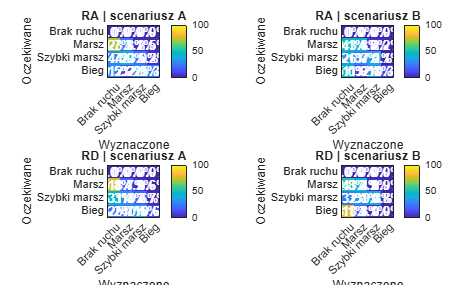

gaits = {['none',"Brak ruchu"],['sw',"Marsz"],['fw',"Szybki marsz"],['run',"Bieg"]};
places = {['hall-along',"scenariusz A"],['hall-end',"scenariusz B"]};
mapTypes = {'RA','RD'};

figure('Color','w');

tiledlayout(numel(mapTypes),numel(places), ...
    'TileSpacing','compact','Padding','compact');

for m = 1:numel(mapTypes)

    mapType = mapTypes{m};

    for p = 1:numel(places)

        placeField = matlab.lang.makeValidName(places{p}(1));

        CM = zeros(numel(gaits),numel(gaits));

        for gt = 1:(numel(gaits))

            s = stats.(mapType).(placeField).(gaits{gt}(1)).samples;

            if sum(s) > 0
                CM(gt,:) = s ./ sum(s);
            end

        end

        nexttile

        imagesc(100*CM);
        axis image

        colormap(parula)
        colorbar

        clim([0 100]);

        xticks(1:size(CM,1));
        yticks(1:size(CM,2));

        xticklabels(cellfun(@(g) g(2),gaits));
        yticklabels(cellfun(@(g) g(2),gaits));

        xlabel('Wyznaczone');
        ylabel('Oczekiwane');

        title(sprintf('%s | %s',mapType,places{p}(2)));

        for r = 1:size(CM,1)
            for c = 1:size(CM,2)

                text(c,r,...
                    sprintf('%.1f%%',100*CM(r,c)),...
                    'HorizontalAlignment','center',...
                    'Color','w',...
                    'FontWeight','bold');

            end
        end

    end
end

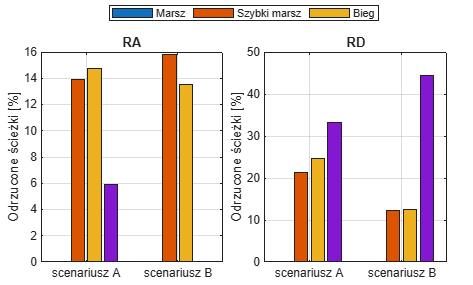


figure('Color','w');

t = tiledlayout(1,2,'TileSpacing','compact','Padding','compact');

for m = 1:numel(mapTypes)

    nexttile

    missRate = zeros(numel(places),numel(gaits)-1);

    for p = 1:numel(places)

        placeField = matlab.lang.makeValidName(places{p}(1));

        for g = 2:(numel(gaits))

            st = stats.(mapTypes{m}).(placeField).(gaits{g}(1));

            totalTracks = ...
                st.acceptedTracks + ...
                st.rejectedTracks;

            if totalTracks > 0
                missRate(p,g) = ...
                    st.rejectedTracks / totalTracks;
            end

        end
    end

    bh = bar(100*missRate);

    ylabel('Odrzucone ścieżki [%]');

    xticklabels(cellfun(@(g) g(2),places));

    title(mapTypes{m});

    grid on
end

leg = legend(cellfun(@(g) g(2),gaits(2:end)));
leg.Layout.Tile = 'north';
leg.Orientation = 'horizontal';